Consider the confound of EN image quality.

Mean: ratio of EN parameter mean between sites

Variance: ratio of EN parameter variance between sites

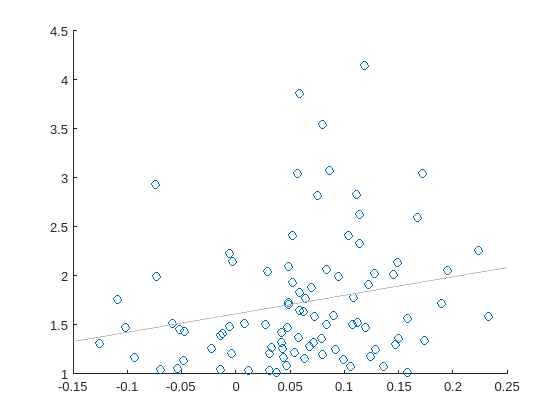

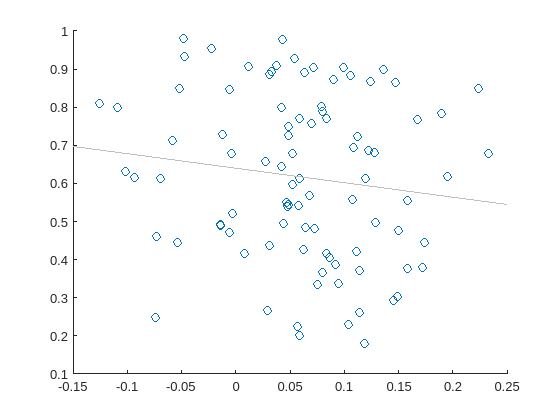

BD


                       Mean      Variance
                     ________    ________

    spearman corr     0.27157    -0.16388
    p                0.015691     0.11884



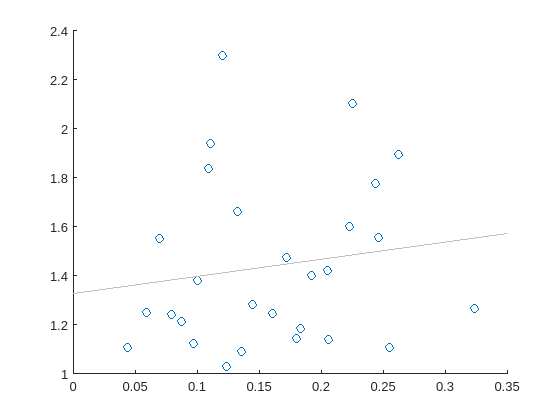

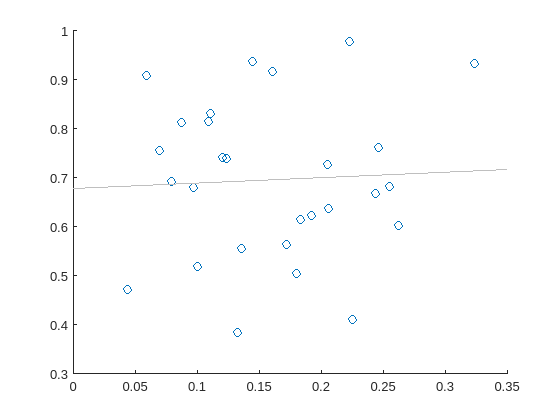

SCA


                      Mean      Variance 
                     _______    _________

    spearman corr    0.21018    -0.036672
    p                0.18602      0.45247



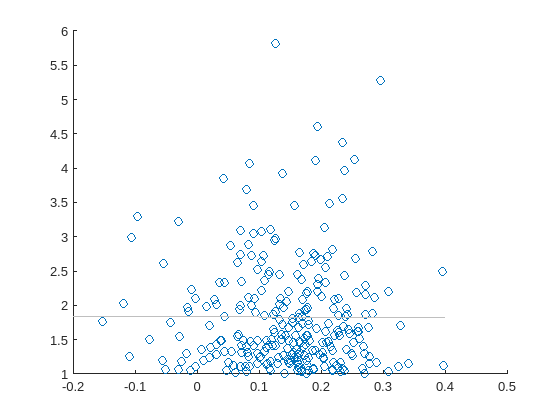

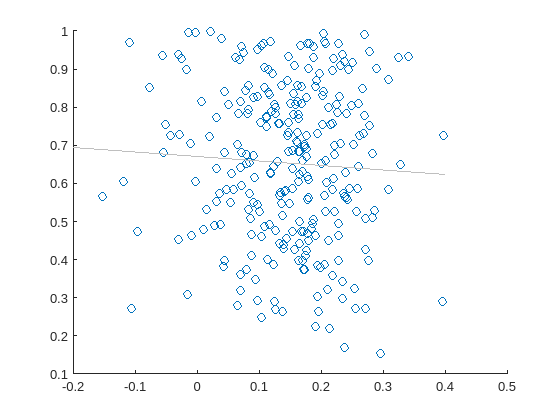

SCZ


                       Mean       Variance 
                     _________    _________

    spearman corr    -0.021694    -0.042392
    p                  0.38505      0.38021



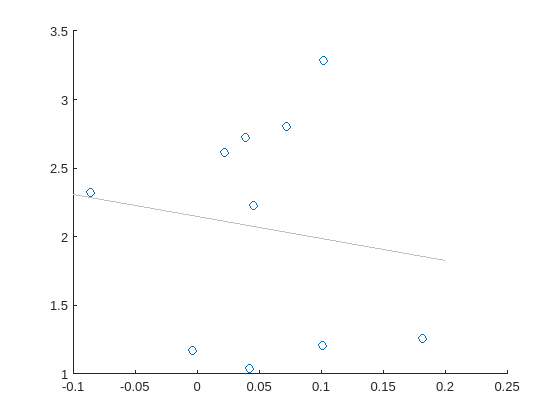

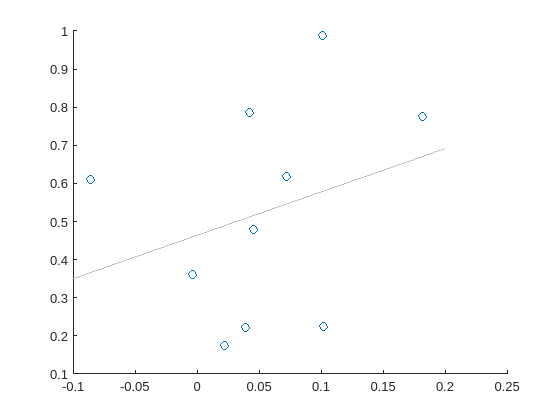

ASD


                      Mean      Variance
                     _______    ________

    spearman corr    0.15152    0.40606 
    p                0.34627    0.17329 



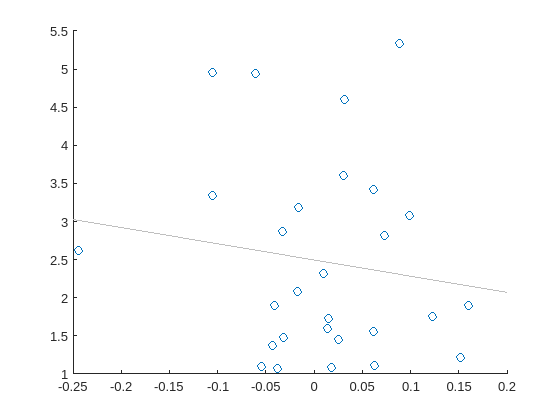

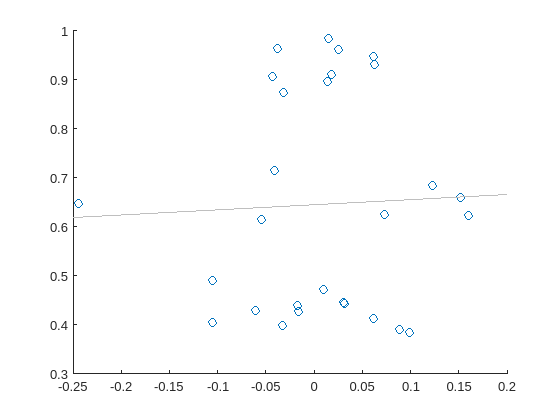

MDD


                       Mean       Variance
                     _________    ________

    spearman corr    -0.055829    0.012042
    p                  0.37909      0.4616



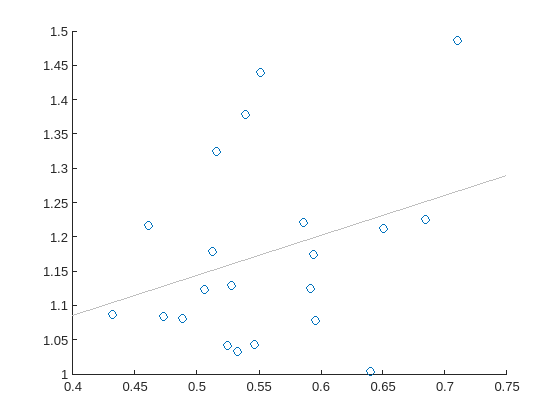

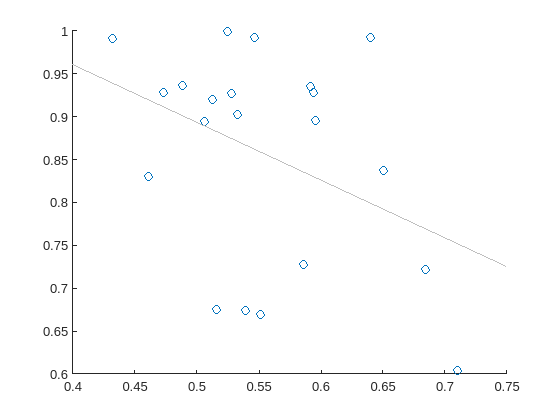

AD


                      Mean      Variance
                     _______    ________

    spearman corr    0.21688    -0.29091
    p                0.26862     0.21562



% Clear workspace and close all figures
clear all
close all

% Define parameters
iCOMBAT = 1; % Flag for applying COMBAT harmonization
smoothKernel = 10; % Smoothing kernel size
iter = 5000; % Number of iterations for Mantel test
hemi = 'lh'; % Hemisphere (e.g., left hemisphere)
type = 'spearman'; % Type of correlation (Spearman rank correlation)
diagnosisString = {'BD', 'SCA', 'SCZ', 'ASD', 'MDD', 'AD'}; % List of diagnoses

nDiag = length(diagnosisString); % Number of diagnoses

% Set the address path based on whether COMBAT is applied
if iCOMBAT == 1
    address = ['derivatives/s', num2str(smoothKernel), 'COMBAT/'];
else
    address = ['derivatives/s', num2str(smoothKernel), '/'];
end

% Load metadata (scanner information)
metadata = readtable(['/projects/kg98/trangc/VBM/data/metadataSBM_extended.csv'], 'VariableNamingRule', 'preserve');

% Load precomputed correlation matrices and site information
load(['output/corr_zmap_combat', num2str(iCOMBAT), '_smooth', num2str(smoothKernel), '_', hemi, '_all.mat'], ...
    'map', 'corDiag', 'corSig', 'siteList');

% Initialize variables for results
varTable = cell(nDiag, 1);
nSite = cell(nDiag, 1);

% Loop through each diagnosis
for iDiag = 1:nDiag
    % Compute variance related to Euler number similarity between sites
    [varTable{iDiag} meanEN{iDiag} varEN{iDiag} nSite{iDiag}]= cor_var_EN(metadata, diagnosisString(iDiag), corDiag{iDiag}, siteList{iDiag}, iter, type);
    % Display results for the current diagnosis
    if size(varTable,1)~=0
        disp(char(diagnosisString(iDiag)))
        disp(varTable{iDiag})
        disp(' ')
        disp(' ')
    end
end

% Suppress warnings related to the last operation
warning('off', 'last');

% Save results to a .mat file
save('output/confound_EN.mat','varTable','meanEN','varEN','nSite')